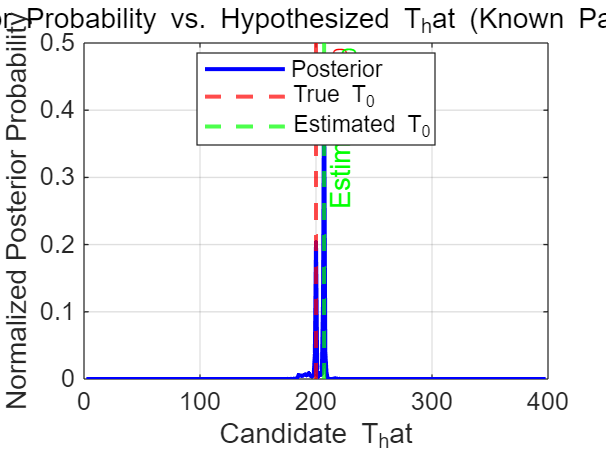

clc; clear; close all;

%% 参数设置
N = 400;            % 总数据点数
T0 = 200;           % 真实突变点
rho = 0.8;          % AR(1) 系数
phi = pi/4;         % AR(2) 极点角度
sigma_alpha = 1;    % AR(1) 噪声标准差
sigma_beta = 1;     % AR(2) 噪声标准差
M = 100;            % Monte Carlo 实验次数

% AR(2) 系数计算
a1 = rho * cos(phi);
a2 = -rho^2 / 4;

%% Monte Carlo 仿真 (参数已知)
mse_known = zeros(M, 1);

for mc = 1:M
    % 生成数据
    x = zeros(N, 1);
    
    % 生成 AR(1) 数据 (n ≤ T0)
    x(1) = sigma_alpha * randn;
    for n = 2:T0
        x(n) = rho * x(n-1) + sigma_alpha * randn;
    end
    
    % 生成 AR(2) 数据 (n > T0)
    x(T0+1) = sigma_beta * randn;
    x(T0+2) = sigma_beta * randn;
    for n = T0+3:N
        x(n) = a1 * x(n-1) + a2 * x(n-2) + sigma_beta * randn;
    end

    %% 计算对数后验概率
    log_posterior = -inf(N, 1); % 初始化为负无穷
    
    for T_hat = 2:N-2
        % 前段 AR(1) 对数似然
        x_front = x(1:T_hat);
        residuals_front = x_front(2:end) - rho * x_front(1:end-1);
        logL_front = -0.5*(T_hat-1)*log(2*pi*sigma_alpha^2) - sum(residuals_front.^2)/(2*sigma_alpha^2);
        
        % 后段 AR(2) 对数似然
        x_back = x(T_hat+1:end);
        if length(x_back) >= 3
            residuals_back = x_back(3:end) - a1*x_back(2:end-1) - a2*x_back(1:end-2);
            logL_back = -0.5*(length(x_back)-2)*log(2*pi*sigma_beta^2) - sum(residuals_back.^2)/(2*sigma_beta^2);
        else
            logL_back = -inf;
        end
        
        log_posterior(T_hat) = logL_front + logL_back;
    end
    
    % MAP 估计
    [~, T_hat_opt] = max(log_posterior);
    mse_known(mc) = (T_hat_opt - T0)^2;
    
    %% 绘制最后一次实验的后验概率曲线
    if mc == M
        % 归一化后验概率（转换为概率值）
        posterior = exp(log_posterior - max(log_posterior)); % 避免数值溢出
        posterior = posterior / sum(posterior(2:N-2));       % 归一化为概率密度
        
        figure;
        plot(2:N-2, posterior(2:N-2), 'b-', 'LineWidth', 1.5);
        hold on;
        xline(T0, 'r--', 'LineWidth', 1.5, 'Label', 'True T_0');
        xline(T_hat_opt, 'g--', 'LineWidth', 1.5, 'Label', 'Estimated T_0');
        title('Posterior Probability vs. Hypothesized T_hat (Known Parameters)');
        xlabel('Candidate T_hat'); ylabel('Normalized Posterior Probability');
        legend('Posterior', 'True T_0', 'Estimated T_0', 'Location', 'best');
        grid on;
    end
end


%% 输出结果
fprintf('任务1 (参数已知) MSE: %.4f\n', mean(mse_known));

任务1 (参数已知) MSE: 584.1800
